# PHY 329 Homework 4

## Ryan Schlimme (eid: rjs4499)

# Problem 18.1

Given the data, perform a fit with 

x = [1, 2, 2.5, 3, 4, 5];
fx = [1, 5, 7, 8, 2, 1];

## Part a) Cubic Spline with Natural End Conditions

fxn = [0, 1, 5, 7, 8, 2, 1, 0];

xx = linspace(1,5)

xx =     1.0000    1.0404    1.0808    1.1212    1.1616    1.2020    1.2424    1.2828    1.3232    1.3636    1.4040    1.4444    1.4848    1.5253    1.5657    1.6061    1.6465    1.6869    1.7273    1.7677    1.8081    1.8485    1.8889    1.9293    1.9697    2.0101    2.0505    2.0909    2.1313    2.1717    2.2121    2.2525    2.2929    2.3333    2.3737    2.4141    2.4545    2.4949    2.5354    2.5758    2.6162    2.6566    2.6970    2.7374    2.7778    2.8182    2.8586    2.8990    2.9394    2.9798


p1 = spline(x, fxn, xx)

p1 =     1.0000    1.0116    1.0454    1.1003    1.1750    1.2681    1.3784    1.5046    1.6455    1.7997    1.9661    2.1433    2.3301    2.5251    2.7271    2.9349    3.1472    3.3626    3.5800    3.7979    4.0153    4.2308    4.4430    4.6509    4.8530    5.0481    5.2355    5.4159    5.5898    5.7581    5.9213    6.0802    6.2355    6.3878    6.5379    6.6864    6.8341    6.9815    7.1291    7.2749    7.4161    7.5499    7.6737    7.7845    7.8797    7.9565    8.0121    8.0437    8.0487    8.0242


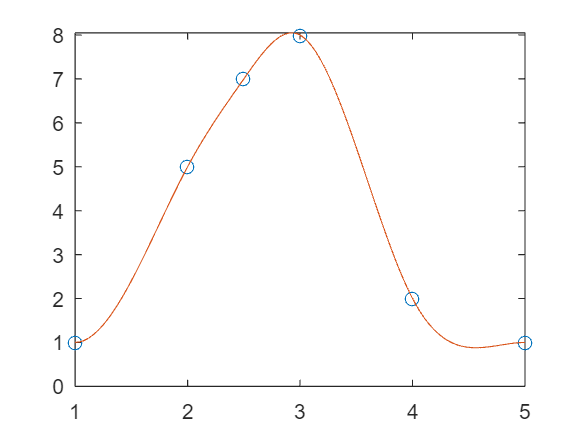


figure(6); plot(x, fx, "o", xx, p1)

## Part b) Cubic Spline with Not-a-Knot End Conditions

p2 = spline(x, fx, xx)

p2 =     1.0000    1.1397    1.2824    1.4279    1.5761    1.7269    1.8801    2.0356    2.1931    2.3526    2.5138    2.6767    2.8411    3.0068    3.1736    3.3415    3.5102    3.6797    3.8497    4.0201    4.1907    4.3615    4.5322    4.7026    4.8727    5.0423    5.2113    5.3794    5.5465    5.7125    5.8772    6.0405    6.2021    6.3621    6.5201    6.6761    6.8298    6.9812    7.1299    7.2742    7.4121    7.5414    7.6601    7.7661    7.8572    7.9314    7.9866    8.0207    8.0317    8.0173


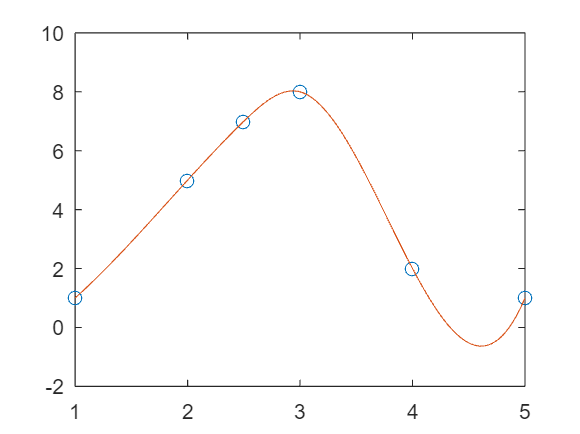


figure(7); plot(x, fx, "o", xx, p2)

## Part c) Piecewise Cubic Hermite Interpolation

p3 = pchip(x, fx,xx)

p3 =     1.0000    1.1616    1.3232    1.4848    1.6465    1.8081    1.9697    2.1313    2.2929    2.4545    2.6162    2.7778    2.9394    3.1010    3.2626    3.4242    3.5859    3.7475    3.9091    4.0707    4.2323    4.3939    4.5556    4.7172    4.8788    5.0407    5.2081    5.3817    5.5592    5.7385    5.9176    6.0943    6.2665    6.4321    6.5890    6.7351    6.8683    6.9864    7.0957    7.2074    7.3194    7.4297    7.5362    7.6368    7.7293    7.8117    7.8818    7.9375    7.9767    7.9973


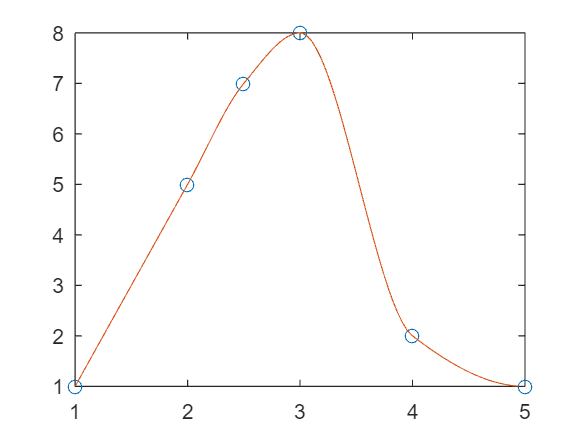


figure(8); plot(x, fx, "o", xx, p3)

# Problem 18.7

## Part a) Cubic spline with not-a-knot end conditions, plot

x = [1,3,5,6,7,9];
fx = [1.000, 2.172, 4.220, 5.430, 4.912, 9.120];

f = @(x) 0.0185*x.^5-0.444*x.^4 + 3.9125*x.^3 - 15.456*x.^2+27.069*x-14.1;

xx = linspace(0,10);

p = spline(x, fx, xx)

p =     0.2734    0.3593    0.4418    0.5213    0.5978    0.6716    0.7428    0.8117    0.8784    0.9432    1.0062    1.0677    1.1277    1.1866    1.2444    1.3015    1.3579    1.4140    1.4698    1.5256    1.5815    1.6379    1.6947    1.7523    1.8109    1.8706    1.9316    1.9941    2.0583    2.1245    2.1927    2.2632    2.3363    2.4120    2.4905    2.5722    2.6571    2.7454    2.8374    2.9332    3.0331    3.1372    3.2457    3.3589    3.4768    3.5997    3.7279    3.8614    4.0005    4.1453


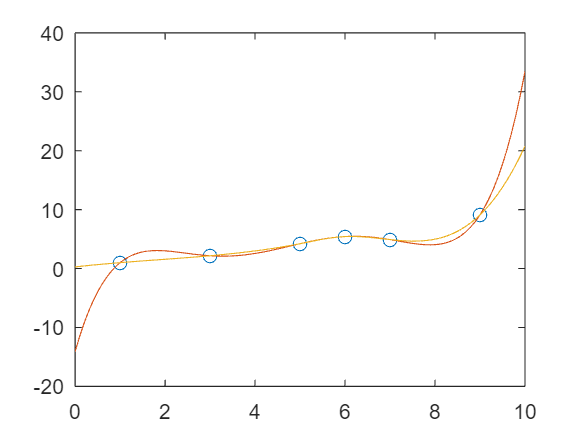


figure; plot(x, fx, "o", xx, f(xx), xx,p)

## Part b) Repeat Using Clamped End Conditions

df = @(x) 5*0.0185*x.^4-4*0.444*x.^3 + 3*3.9125*x.^2 - 2*15.456*x+27.069;

xu = df(9)

xu = 11.7870

xl = df(1)

xl = 6.2110

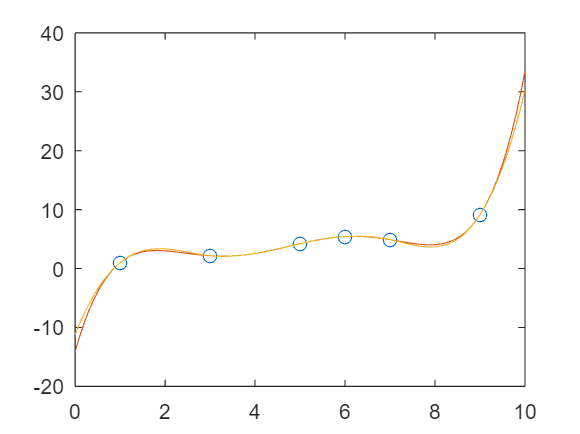


xnew = [6.2110, 1.000, 2.172, 4.220, 5.430, 4.912, 9.120, 11.7870];

xx = linspace(0,10);

p1 = spline(x, xnew, xx);



figure(1); plot(x, fx, "o", xx, f(xx), xx,p1)

# Problem 18.11

## Part a) Quartic Polynomial Fit

f = @(x) 1./(1+25*x.^2);

xvals = linspace(-1,1,5)

xvals =    -1.0000   -0.5000         0    0.5000    1.0000



fvals = []


fvals =

     []




for i = -1:0.5:1
    fvals(end + 1) = f(i);
end

p = polyfit(xvals, fvals, 4)

p =     3.3156   -0.0000   -4.2772    0.0000    1.0000



fx = f(xvals)

fx =     0.0385    0.1379    1.0000    0.1379    0.0385



xv = linspace(-1,1,1000);

fv = polyval(p, xv)

fv =     0.0385    0.0291    0.0199    0.0107    0.0018   -0.0071   -0.0159   -0.0245   -0.0330   -0.0414   -0.0496   -0.0578   -0.0658   -0.0737   -0.0815   -0.0892   -0.0968   -0.1042   -0.1115   -0.1188   -0.1259   -0.1329   -0.1397   -0.1465   -0.1532   -0.1597   -0.1661   -0.1725   -0.1787   -0.1848   -0.1908   -0.1967   -0.2025   -0.2082   -0.2138   -0.2193   -0.2246   -0.2299   -0.2351   -0.2401   -0.2451   -0.2500   -0.2547   -0.2594   -0.2640   -0.2684   -0.2728   -0.2771   -0.2813   -0.2853


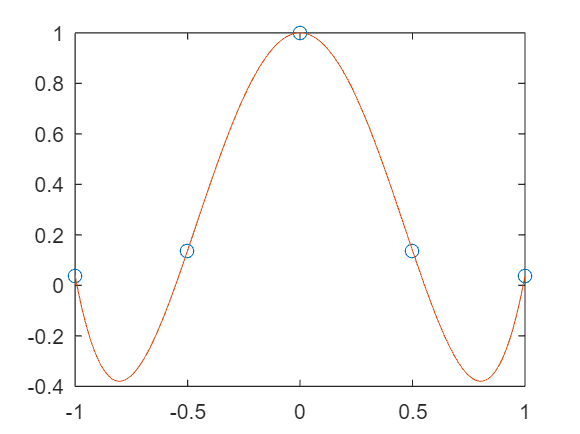


figure(2); plot(xvals, fx, "o", xv, fv)

## Part b) Linear Spline

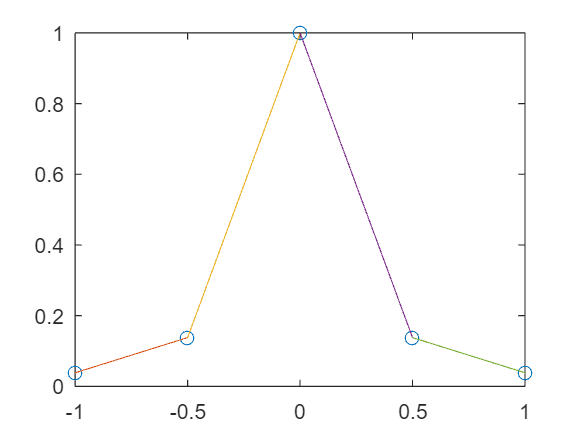

a = [];
b = [];

for i = -1:0.5:1
    a(end+1) = f(i);
    b(end+1) = (f(i+0.5)-f(i))/0.5;
end

xvals1 = linspace(-1,-0.5, 100);
xvals2 = linspace(-0.5,0,100);
xvals3 = linspace(0,0.5,100);
xvals4 = linspace(0.5,1,100);

figure(3); plot(xvals, fx, "o", xvals1, a(1)+b(1)*(xvals1+1), xvals2, a(2)+b(2)*(xvals2+0.5), xvals3, a(3)+b(3)*(xvals3), xvals4, a(4)+b(4)*(xvals4-0.5))

## Part c) Cubic Spline

I = spline(xvals, f(xvals))

I = struct with fields:
      form: 'pp'
    breaks: [-1 -0.5000 0 0.5000 1]
     coefs: [4×4 double]
    pieces: 4
     order: 4
       dim: 1



xv = linspace(-1,1,1000)

xv =    -1.0000   -0.9980   -0.9960   -0.9940   -0.9920   -0.9900   -0.9880   -0.9860   -0.9840   -0.9820   -0.9800   -0.9780   -0.9760   -0.9740   -0.9720   -0.9700   -0.9680   -0.9660   -0.9640   -0.9620   -0.9600   -0.9580   -0.9560   -0.9540   -0.9520   -0.9499   -0.9479   -0.9459   -0.9439   -0.9419   -0.9399   -0.9379   -0.9359   -0.9339   -0.9319   -0.9299   -0.9279   -0.9259   -0.9239   -0.9219   -0.9199   -0.9179   -0.9159   -0.9139   -0.9119   -0.9099   -0.9079   -0.9059   -0.9039   -0.9019


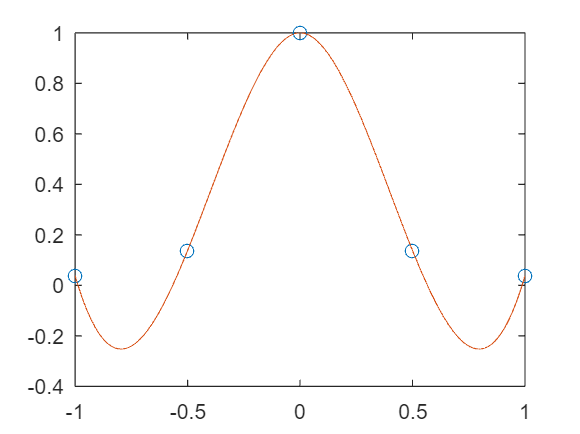


figure(4); plot(xvals, fx, "o", xv, ppval(I, xv))

# Problem 19.4

## Part b) Single Trapezoidal Rule

f = @(x) 1 - x - 4*x.^3 + 2*x.^5; 

fl = f(-2);
f2 = f(4);

I = 6*0.5*(fl+f2)

I = 5280


(I - 1104)/1104*100

ans = 378.2609

## Part c) Composite Trapezoidal Rule

I2 = trap(f, -2,4, 2)

I2 = 2634


(I2 - 1104)/1104*100

ans = 138.5870


I4 = trap(f, -2,4, 4)

I4 = 1.5169e+03


(I4 - 1104)/1104*100

ans = 37.3981

## Part d) Simpson's 1/3

a = -2; b = 4; n = 2;

h = (b - a)/n; 

X = f(a)+f(b); 
  
Odd = 0; 
Even = 0; 
for i = 1:2:n-1 
    xi=a+(i*h); 
    Odd=Odd+f(xi); 
end
for i = 2:2:n-2 
    xi=a+(i*h); 
    Even=Even+f(xi); 
end

I = (h/3)*(X+4*Odd+2*Even); 

I 

I = 1752

(I - 1104)/1104*100

ans = 58.6957

## Part e) Simpson's 3/8

I = simpson38(f, -2, 4, 6)

I = 1122


(I - 1104)/1104*100

ans = 1.6304

## Part f) Boole's Rule

I = boole(f, -2, 4, 2)

I = 1104


(I - 1104)/1104*100

ans = 0

# Problem 19.5

x = [0, 0.1, 0.3, 0.5, 0.7, 0.95, 1.2];
fx = [1, 0.9048, 0.7408, 0.6065, 0.4966, 0.3867, 0.3012];

## Part b) Trapezoidal Rule and Error

I = trapz(x, fx)

I = 0.7012


(I - 0.69880)/0.69880*100

ans = 0.3492

## Part c) Trapezoidal and Simpson's Rule

I = simps(x, fx)

I = 0.6988


(I - 0.69880)/0.69880*100

ans = -0.0072

# Problem 19.8

## Part a) Integration

t = [1, 2, 3.25, 4.5, 6, 7, 8, 8.5, 9, 10];
v = [5, 6, 5.5, 7, 8.5, 8, 6, 7, 7, 5];

z = trapz(t, v)

z = 60.1250

z / (10-1)

ans = 6.6806

## Part b) Cubic Fit

polyfit(t, v, 3)

ans =    -0.0180    0.1753    0.0603    4.8507



v = @(t) -0.0180*t.^3 +0.1753*t.^2+0.0603*t+4.8507

v = function_handle with value:
    @(t)-0.0180*t.^3+0.1753*t.^2+0.0603*t+4.8507



integral(v, 1, 10)

ans = 60.0206

v(t) = -0.0180t^3 +0.1753t^2+0.0603t+4.8507

# Problem 19.13

x = [0, 4, 6, 8, 12, 16, 20];
rho = [4.00, 3.95, 3.89, 3.80, 3.60, 3.41, 3.30];
A = [100, 103, 106, 110, 120, 133, 150];

integrand = rho.*A

integrand =   400.0000  406.8500  412.3400  418.0000  432.0000  453.5300  495.0000



m = trapz(x, integrand)

m = 8.6314e+03

# Problem 19.10

## Part a) Composite Trapezoidal

f = @(z) 200 * (z / (5+z))*exp(-2*z/30);
fz = @(z) 200 * (z / (5+z))*exp(-2*z/30)*z;

trap(f, 0, 30, 6)

ans = 1.4027e+03

trap(fz, 0, 30, 6) / trap(f, 0 ,30, 6)

ans = 13.7199

## Part b) Simpson's 1/3 Rule

f = @(z) 200 * (z / (5+z))*exp(-2*z/30);
fz = @(z) 200 * (z / (5+z))*exp(-2*z/30)*z;

a = 0; b = 30; N = 6;

h = ((b-a)/2)/N; 
x = linspace(a,b,N);

I = 0;
for i = 1:N-1
    I = I + h/3*(f(x(i)) + 4*f((x(i)+x(i+1))/2) + f(x(i+1)));
end

n1 = I

n1 = 1.2308e+03


I = 0;
for i = 1:N-1
    I = I + h/3*(fz(x(i)) + 4*fz((x(i)+x(i+1))/2) + fz(x(i+1)));
end

n2 = I;

n2/n1

ans = 13.0971

# Problem 20.1

## Romberg integration

f = @(x) x.^2 + 2 + 1/x.^2;

romberg(f, 1, 2, 0.5)

ans = 4.8335


(4.8335-(29/6))/(29/6)*100

ans = 0.0034

# Problem 20.2

## Part b) Romberg (0.5% error)

f = @(x) -0.055*x.^4 + 0.86*x.^3 - 4.2*x.^2 + 6.3*x + 2;

romberg(f, 0, 8, 0.5)

ans = 20.9920

## Part c) Three-Point Gauss Quadrature

f = @(t) (-0.055*(4*t+4).^4 + 0.86*(4*t+4).^3 - 4.2*(4*t+4).^2 + 6.3*(4*t+4) + 2)*4;

0.5555556*f(-0.7745967)+0.8888889*f(0)+0.5555556*f(0.7745967)

ans = 20.9920

Using a change of variables, we can perform three point Gauss Quadrature using the following points and weights.

## Part d) Integral Function

f = @(x) -0.055*x.^4 + 0.86*x.^3 - 4.2*x.^2 + 6.3*x + 2;

integral(f,0,8)

ans = 20.9920

# Problem 20.7

f = @(T) 1000*(0.132+1.56e-4*T+2.64e-7*T.^2);

x = linspace(0,300,301)

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



vals = []


vals =

     []



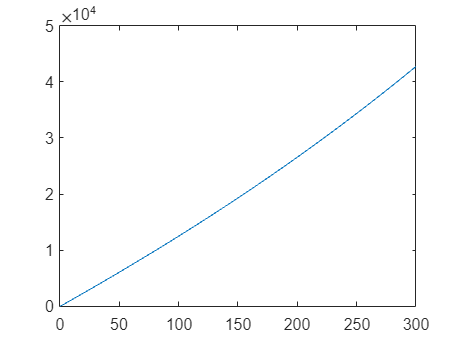


for Tmax = -100:1:200
    vals(end+1) = integral(f,-100,Tmax);
end

figure(1); plot(x, vals)

# Problem 20.14

t = [0,0.2,0.4,0.6,0.8,1,1.2];
i = 1e-3*[0.2, 0.3683, 0.3819,0.2282,0.0486,0.0082,0.1441];

p = polyfit(t,i,5)

p =    -0.0037    0.0115   -0.0104    0.0015    0.0009    0.0002



f = @(t) -0.0037*t.^5 + 0.0115*t.^4 - 0.0104*t.^3 + 0.0015*t.^2 + 0.0009*t + 0.0002;

vals = []


vals =

     []




x = 0:0.0001:1.2

x =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


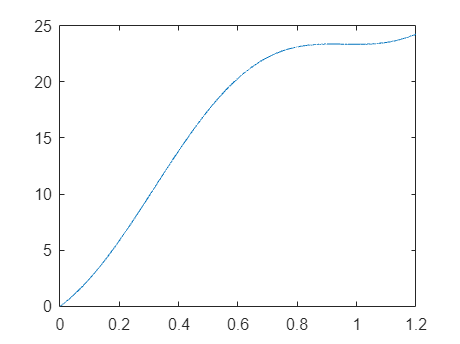


for Tmax = 0:0.0001:1.2
    vals(end+1) = integral(f,0,Tmax)/1e-5;
end

figure(1); plot(x, vals)

# Problem 21.9

x = [0.6,1.5,1.6,2.5,3.5];
f = [0.9036,0.3734,0.3261,0.08422,0.01596];

dfx = [1.5+0.6, 1.6+1.5,2.5+1.6, 3.5+2.5]/2

dfx =     1.0500    1.5500    2.0500    3.0000



df = [(0.3734-0.9036)/(1.5-0.6), (0.3261-0.3734)/(1.6-1.5), (0.08422-0.3261)/(2.5-1.6), (0.01596-0.08422)/(3.5-2.5)]

df =    -0.5891   -0.4730   -0.2688   -0.0683


# Problem 21.18

x = 0:1:10;
y = [1.4,2.1,3.3,4.8,6.8,6.6,8.6,7.5,8.9,10.9,10];

diff(y)

d1 =     0.7000    1.2000    1.5000    2.0000   -0.2000    2.0000   -1.1000    1.4000    2.0000   -0.9000



diff(y,2)

ans =     0.5000    0.3000    0.5000   -2.2000    2.2000   -3.1000    2.5000    0.6000   -2.9000


# Problem 21.26

t = [0,0.1,0.2,0.3,0.5,0.7];
i = [0,0.16,0.32,0.56,0.84,2.0];

4*diff(i)./diff(t)

ans =     6.4000    6.4000    9.6000    5.6000   23.2000


# Problem 21.41

v = @(t) 2*t/sqrt(1+t.^2);

actual = 2/(1+5^2)^(3/2)

actual = 0.0151


d2 = (v(5)-v(4.75))/0.25;
d1 = (v(5)-v(4.5))/0.5;

pred = 4/3*d2-1/3*d1

pred = 0.0158


(pred-actual)/actual*100

ans = 4.7649

# Define Our Functions

% Composite Trapezoidal Integration

function I = trap(func, a, b, n, varargin)
if nargin<3, error("at least 3 args required"), end
if ~(b>a), error("upper bound must be greater than lower"), end
if nargin<4 || isempty(n), n = 100; end
x = a; h = (b-a)/n;
s = func(a, varargin{:});
for i = 1: n-1
    x = x+h;
    s = s+2*func(x, varargin{:});
end
s = s + func(b, varargin{:});
I = (b-a)*s/(2*n);
end

% Romberg Integration
function [q,ea,iter] = romberg(func,a,b,es,maxit,varargin)
if nargin<3, error("at least 3 args required"),end
if nargin<4||isempty(es), es=0.000001;end
if nargin<5||isempty(maxit), maxit=50;end
n = 1;
I(1,1) = trap(func,a,b,n,varargin{:});
iter = 0;
while iter < maxit
    iter = iter + 1;
    n = 2^iter;
    I(iter+1,1) = trap(func,a,b,n,varargin{:});
    for k = 2:iter+1
        j = 2+iter-k;
        I(j,k) = (4^(k-1)*I(j+1,k-1)-I(j,k-1))/(4^(k-1)-1);
    end
    ea = abs((I(1,iter+1)-I(2,iter))/I(1,iter+1))*100;
    if ea<=es, break; end
end
q = I(1,iter+1);
end


% Simpson's Rule (by Damien Garcia)
function z = simps(x,y,dim)
%SIMPS  Simpson's numerical integration.
%   The Simpson's rule for integration uses parabolic arcs instead of the
%   straight lines used in the trapezoidal rule.
%
%   Z = SIMPS(Y) computes an approximation of the integral of Y via the
%   Simpson's method (with unit spacing). To compute the integral for
%   spacing different from one, multiply Z by the spacing increment.
%
%   For vectors, SIMPS(Y) is the integral of Y. For matrices, SIMPS(Y) is a
%   row vector with the integral over each column. For N-D arrays, SIMPS(Y)
%   works across the first non-singleton dimension.
%
%   Z = SIMPS(X,Y) computes the integral of Y with respect to X using the
%   Simpson's rule. X and Y must be vectors of the same length, or X must
%   be a column vector and Y an array whose first non-singleton dimension
%   is length(X). SIMPS operates along this dimension.
%
%   Z = SIMPS(X,Y,DIM) or SIMPS(Y,DIM) integrates across dimension DIM of
%   Y. The length of X must be the same as size(Y,DIM).
%
%   Examples:
%   --------
%   % The integration of sin(x) on [0,pi] is 2
%   % Let us compare TRAPZ and SIMPS
%   x = linspace(0,pi,6);
%   y = sin(x);
%   trapz(x,y) % returns 1.9338
%   simps(x,y) % returns 2.0071
%
%   If Y = [0 1 2
%           3 4 5
%           6 7 8]
%   then simps(Y,1) is [6 8 10] and simps(Y,2) is [2; 8; 14]
%
%   -- Damien Garcia -- 08/2007, revised 11/2009
%   website: <a
%   href="matlab:web('http://www.biomecardio.com')">www.BiomeCardio.com</a>
%
%   See also CUMSIMPS, TRAPZ, QUAD.
%   Adapted from TRAPZ
%--   Make sure x and y are column vectors, or y is a matrix.
perm = []; nshifts = 0;
if nargin == 3 % simps(x,y,dim)
  perm = [dim:max(ndims(y),dim) 1:dim-1];
  yp = permute(y,perm);
  [m,n] = size(yp);
elseif nargin==2 && isscalar(y) % simps(y,dim)
  dim = y; y = x;
  perm = [dim:max(ndims(y),dim) 1:dim-1];
  yp = permute(y,perm);
  [m,n] = size(yp);
  x = 1:m;
else % simps(y) or simps(x,y)
  if nargin < 2, y = x; end
  [yp,nshifts] = shiftdim(y);
  [m,n] = size(yp);
  if nargin < 2, x = 1:m; end
end
x = x(:);
if length(x) ~= m
  if isempty(perm) % dim argument not given
    error('MATLAB:simps:LengthXmismatchY',...
          'LENGTH(X) must equal the length of the first non-singleton dimension of Y.');
  else
    error('MATLAB:simps:LengthXmismatchY',...
          'LENGTH(X) must equal the length of the DIM''th dimension of Y.');
  end
end
%-- The output size for [] is a special case when DIM is not given.
if isempty(perm) && isequal(y,[])
  z = zeros(1,class(y));
  return
end
%-- Use TRAPZ if m<3
if m<3
    if exist('dim','var')
        z = trapz(x,y,dim);
    else
        z = trapz(x,y);
    end
    return
end
%-- Simpson's rule
y = yp;
clear yp
dx = repmat(diff(x,1,1),1,n);
dx1 = dx(1:end-1,:);
dx2 = dx(2:end,:);
alpha = (dx1+dx2)./dx1/6;
a0 = alpha.*(2*dx1-dx2);
a1 = alpha.*(dx1+dx2).^2./dx2;
a2 = alpha.*dx1./dx2.*(2*dx2-dx1);
z = sum(a0(1:2:end,:).*y(1:2:m-2,:) +...
    a1(1:2:end,:).*y(2:2:m-1,:) +...
    a2(1:2:end,:).*y(3:2:m,:),1);
if rem(m,2) == 0 % Adjusting if length(x) is even   
    state0 = warning('query','MATLAB:nearlySingularMatrix');
    state0 = state0.state;
    warning('off','MATLAB:nearlySingularMatrix')
    C = vander(x(end-2:end))\y(end-2:end,:);
    z = z + C(1,:).*(x(end,:).^3-x(end-1,:).^3)/3 +...
        C(2,:).*(x(end,:).^2-x(end-1,:).^2)/2 +...
        C(3,:).*dx(end,:);
    warning(state0,'MATLAB:nearlySingularMatrix')
end
%-- Resizing
siz = size(y); siz(1) = 1;
z = reshape(z,[ones(1,nshifts),siz]);
if ~isempty(perm), z = ipermute(z,perm); end
end

% Simpson's 3/8 Rule (by JPS)
function integral = simpson38(f , a , b , n)
%{
description:
    this function evaluates the integral of a mathematical function f
    between the limits a and b using the simpson's 1/3 formula given by,
        I = 3 * h / 8 * (f(a) + f(b) + 3 * f(x_interiors))
    
inputs:
    1. f = the function which to be integrated.
    2. a = lower limit of the integral.
    3. b = upper limit of the integral.
    4. n = the no of intervals to which the domain is to be split. note
    that n is always even for this case.
    note: n is an optional argument. if n is not specified, the function
    splits the interval into 60 pieces.
outputs:
    1. integral = this will give the value of the integral of the
    mathematical function f between the limits a and b.
%}
    %adding robustness - argumental pre-check
    if nargin < 3
        error('not enough input arguments. minimum 3 arguments needed.')
    end
    
    if a > b
        error("lowerlimit can't be greater than upperlimit.")
    end
    
    if mod(n , 3) ~= 0
        error("n must be a multiple of 3.")
    end
    
    if nargin < 4
        n = 60;
    end
        
    %calculate h value
    h = (b - a) / n;
    
    %evaluate the function values
    x = linspace(a , b , n + 1);
    for i = 1 : n + 1
       fofx(i) = f(x(i)); 
    end
 
    %split up the points
    g = fofx;
    g(1) = [];
    g(end) = [];
    inot3 = 0; %not a 3 multiple
    i3 = 0; %is a 3 multiple
    
    global g_3;
    for j = 1 : length(g)
        if mod(j , 3) == 0
            i3 = i3 + 1;
            g_3(i3) = g(j);
        else
            inot3 = inot3 + 1;
            g_not3(inot3) = g(j);
        end
    end
    
    if isempty(g_3)
        g_3 = 0;
    end
    
    %evaluate the integral
    integral = 3 * h / 8 * (fofx(1) + fofx(end) + 3 * sum(g_not3) + 2 * sum(g_3));
   
end

function r = boole(f,a,b,n)
h = (b - a) / (n * 4);
r = 7 * f(a);
x = a + h;
for i = 1 : n-1
    r = r + 32 * f(x);
    x = x + h;
    r = r + 12 * f(x);
    x = x + h;
    r = r + 32 * f(x);
    x = x + h;
    r = r + 14 * f(x);
    x = x + h;
end
r = r + 32 * f(x);
x = x + h;
r = r + 12 * f(x);
x = x + h;
r = r + 32 * f(x);
r = r + 7 * f(b);
r = r * h*2/45;
end

% Linear Splines (by Madhan Ravi)
function out=LSplines(x,pointx,pointy)
n=length(pointx);
for i=2:n
 t1(i)= (pointx(i)-x);
 b1(i)= (pointx(i)-pointx(i-1));
 t2(i)= (x-pointx(i-1));
 b2(i)= (pointx(i)-pointx(i-1));
end
P=cell(1,n);
P{1}=0;
for i=2:n
  P{i}= P{i-1}+pointy(i-1)*t1(i)/b1(i)+pointy(i)*t2(i)/b2(i);
end
out=P;
end